# Astro 423 Lesson 2

## Advaced Matlab Skills

Lt Col Nathan Collins - Jan 2023

Modified by Lt Col Greg Frey -  August 2023 - Added section on using numerical solvers to find roots

### [Vectorization](https://www.mathworks.com/help/matlab/matlab_prog/vectorization.html)

Vectorization is a way to clean up the appearance of code to make it look more like a mathematical expression and easier to understand.  Vectorization removes the need for loops and greatly improves the run times for the code.

#### Example 1: Basic Vectorization 1

a = 7378.137; % semi-major axis -km
e = 0.1; % eccentricty -unitless
nu = linspace(0,2*pi,360)'; % true anomaly -radians

%% no preallocation or vectorization
tic
for k = 1:length(nu)
    R(k) = (a*(1-e^2))/(1+e*cos(nu(k)));
end
t1 = toc

t1 =    0.037055300000000



%% preallocation but no vectorization
R2 = zeros(length(nu),1);
tic
for k = 1:length(nu)
    R2(k,1) = (a*(1-e^2))/(1+e*cos(nu(k)));
end
t2 = toc

t2 =    0.004022700000000



%% vectorization
tic
R3 = (a*(1-e^2))./(1+e*cos(nu)); % uses ./  Note that many built-in matlab function like sin and cos are already vectorized. 
t3 = toc

t3 =    0.002251900000000


#### Example 2: Basic Vectorization 2

[e,E] = meshgrid(0:.01:1,0:pi/180:2*pi); % define eccentricty and Eccentric anomaly

[rn,cn] = size(e);

%% calculate Mean anomaly with loops
M = zeros(rn,cn);
tic
for kr = 1:rn               % loops through rows
    for kc = 1:cn           % loops through columns
        M(kr,kc) = E(kr,kc) - e(kr,kc)*sin(E(kr,kc));
    end
end
t1 = toc

t1 =    0.037550900000000


%% calculate Mean anomaly with vectorization
tic
M2 = E - e.*sin(E); % uses .*
t2 = toc

t2 =    0.008183300000000


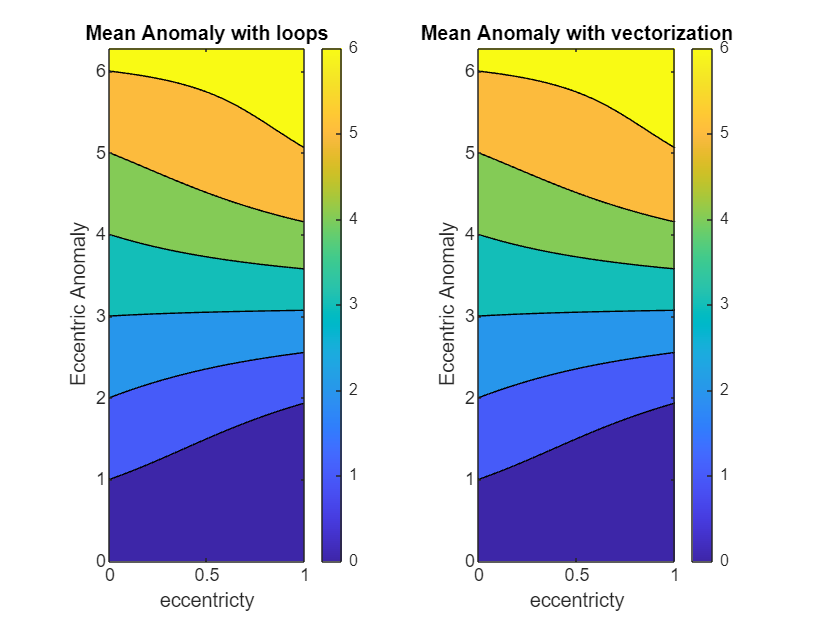


%% plot and verify M and M2 are the same
subplot(1,2,1) % left plot
contourf(e,E,M)
xlabel('eccentricty')
ylabel('Eccentric Anomaly')
title('Mean Anomaly with loops')
colorbar

subplot(1,2,2) % right plot
contourf(e,E,M2)
xlabel('eccentricty')
ylabel('Eccentric Anomaly')
title('Mean Anomaly with vectorization')
colorbar

#### Example 3: Basic Vectorization 3

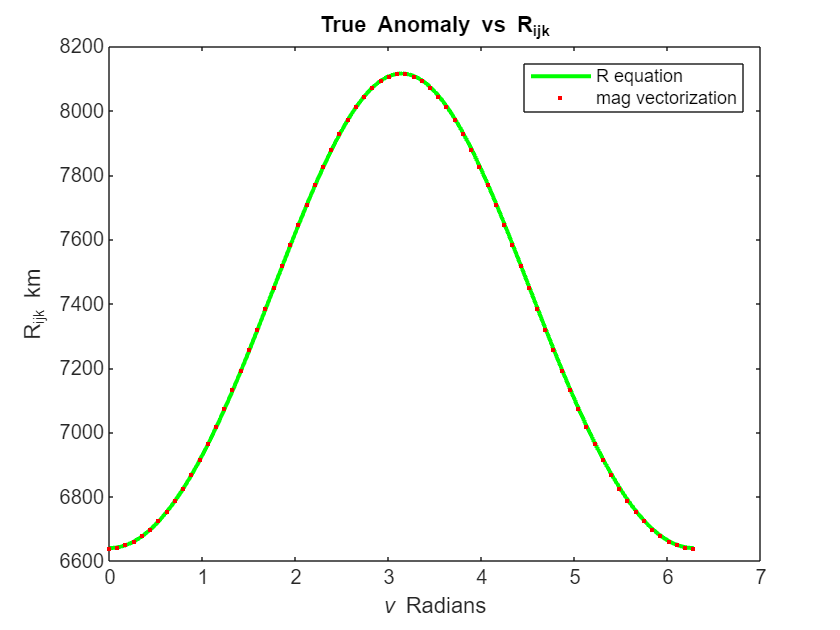

%% define orbit COEs
wgs84data
a = 7378.137; % semi-major axis -km
e = 0.1; % eccentricty -unitless
nu2 = linspace(0,2*pi,72)'; % true anomaly -radians
incl = deg2rad(45); % inclination -radians
raan = deg2rad(30); % RAAN -radians
argp = deg2rad(270); % argument of perigee -radians


%% calculate the Rijk  & Vijk vectors for one orbit
Rijk = zeros(length(nu2),3); %Preallocated R
Vijk = zeros(length(nu2),3); %Preallocated V
for k = 1:length(nu2)
    [rpqw,vpqw]=RVpqw(a,e,nu2(k));
    [rijk,vijk]=RVijk(rpqw,vpqw,incl,raan,argp);
    Rijk(k,:) = rijk';
    Vijk(k,:) = vijk';
end

%% calculate magnitude of Rijk using vectorization
mag_Rijk = sum(Rijk.*Rijk,2).^0.5; % uses .* and .^ Sums along columns of the Rijk.*Rijk array to obtain magnitude.

%% validate R from Example 1 equals mag_Rijk
figure
plot(nu,R','g-','LineWidth',2)
hold on
plot(nu2,mag_Rijk,'r.','LineWidth',2)
xlabel('\nu Radians')
ylabel('R_{ijk} km')
title('True Anomaly vs R_{ijk}')
legend('R equation','mag vectorization')
hold off

### [Logical indexing](https://www.mathworks.com/help/matlab/math/array-indexing.html#MatrixIndexingExample-3)

Indexing Matlab arrays with logical values (1s and 0s) is a fast and easy way to parse large datasets.

#### Example 4: Coloring a plot bases on value

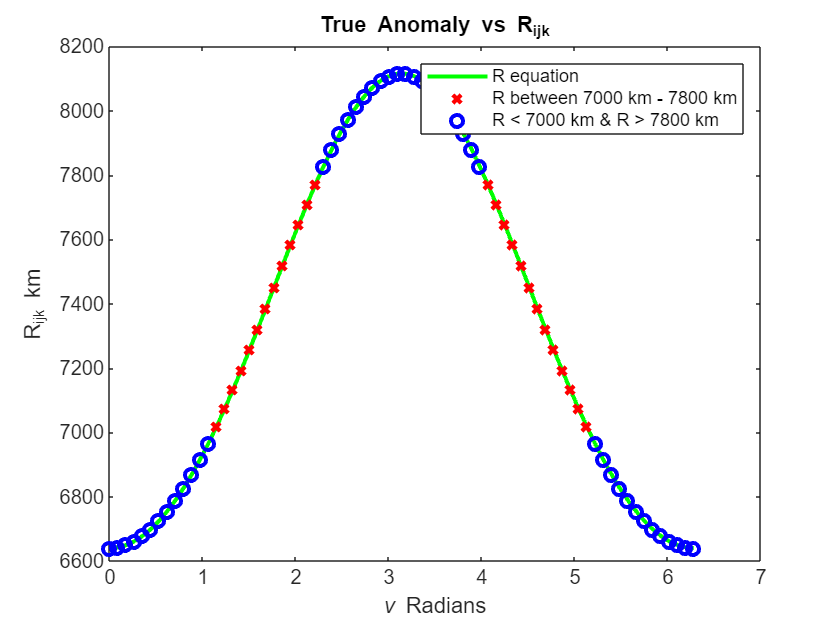

R_indx = mag_Rijk > 7000 & mag_Rijk < 7800;

%% plot 
figure
plot(nu,R','g-','LineWidth',2)
hold on
plot(nu2(R_indx),mag_Rijk(R_indx),'rx','LineWidth',2)
plot(nu2(~R_indx),mag_Rijk(~R_indx),'bo','LineWidth',2)
xlabel('\nu Radians')
ylabel('R_{ijk} km')
title('True Anomaly vs R_{ijk}')
legend('R equation','R between 7000 km - 7800 km','R < 7000 km & R > 7800 km')
hold off

### Plotting

#### Example 5: Plotting Reentry Velocity

The reentry velocity of a vehicle can be modeled as $V=V_{E}e^{\left [ \frac{\rho_{ _{0}}}{2\Delta\beta sin(\phi_{E})} e^{-\beta h} \right ]}$ where:

$V$ is the velocity

$V_{E}$ is the velocity at reentry

$\rho_{ _{0}}$ is the atmospheric density at sea level $\bf{1.225 \ kg/m^{3}}$

$\Delta = \frac{m}{C_{D} A}$ is the ballistic coefficient

$\beta$ is the atmospheric scale height $\bf{\frac{1}{7.315 \ km}}$

$\phi_{E}$ is the vehicle's flight-path angle

$h$ is the height

**Problem**: plot reentry velocity at various flight-path angles $\bf{\phi_{E}=15^o, \ 45^o, \ 85^o}$.

**Assume:** $\bf{\Delta = 2000 \ kg/m^{2}}$


$$\bf{V_{E} =  \ 8 \ km/s}$$


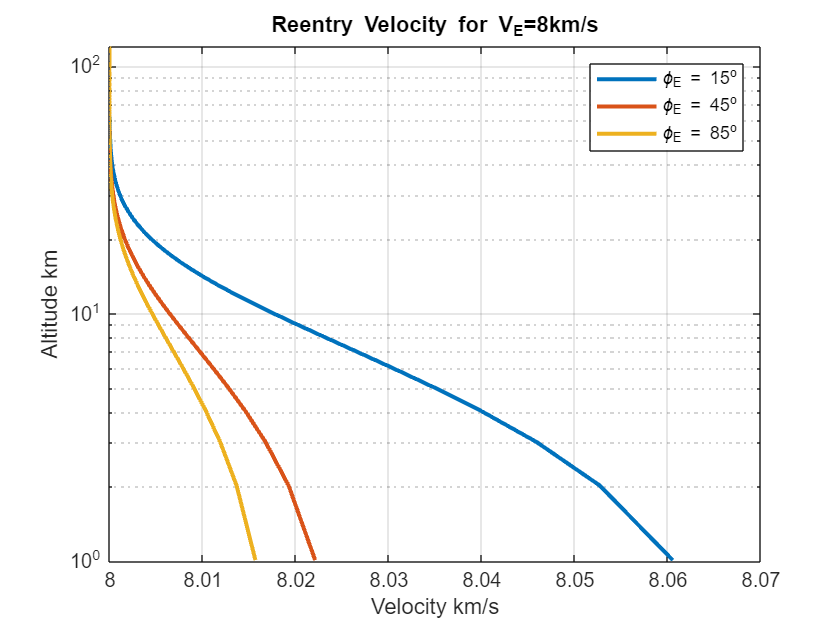

% define constants
rho0 = 1.225; % kg/m^3
beta = 1/7.315; % 1/km
BC = 2000; % kg/m^2
h = linspace(0,120,120); % heights in km

% plot set V_E to 8 km/s
V_E = 8; % km/s
phi_E = deg2rad([15,45,85]); % rad
[h_8,phi_E_8] =meshgrid(h,phi_E);

V = V_E.*exp((rho0)./(2.*BC.*beta.*sin(phi_E_8)).*exp(-beta.*h_8));

figure
semilogy(V(1,:),h,V(2,:),h,V(3,:),h,'LineWidth',2) %Semilogy creates a plot with a logarithmic y axis. 
xlabel('Velocity km/s')
ylabel('Altitude km')
grid on
title('Reentry Velocity for V_{E}=8km/s')
legend('\phi_E = 15^o','\phi_E = 45^o','\phi_E = 85^o')

#### Example 6: Plotting the Earth and Moon in 3D

Plotting celestial bodies to scale in 3D.

planet3D.m is from the Matllab file exchange ([link](https://www.mathworks.com/matlabcentral/fileexchange/86483-3d-earth-and-celestial-bodies-planet3d)).

Tamas Kis (2023). 3D Earth and Celestial Bodies (planet3D) (https://github.com/tamaskis/planet3D-MATLAB/releases/tag/v5.2.0), GitHub.

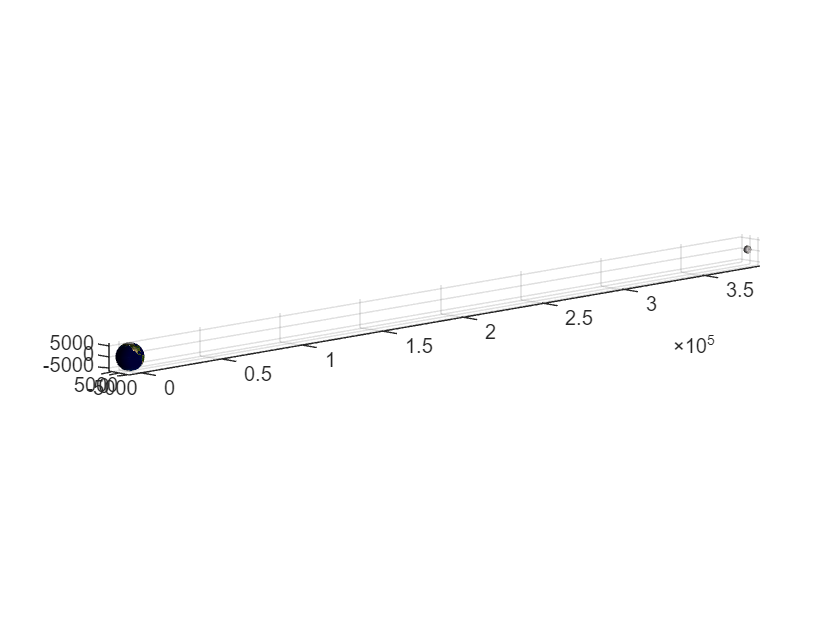

opts_earth.RefPlane = 'equatorial';
opts_earth.Units = 'km';
opts_earth.Position = [0,0,0];

figure;
planet3D('Earth',opts_earth);
hold on

opts_moon.RefPlane = 'equatorial';
opts_moon.Units = 'km';
opts_moon.Position = [384400,0,0];
planet3D('Moon',opts_moon);

grid on;
light('Position',[0,-1,0]);
view(-45,10)
hold off

#### Example 7: Plotting an orbit with 3D Earth

3D plot of the Earth and an orbit with the orbit positions positions colored based on orbital speed at the respective point.

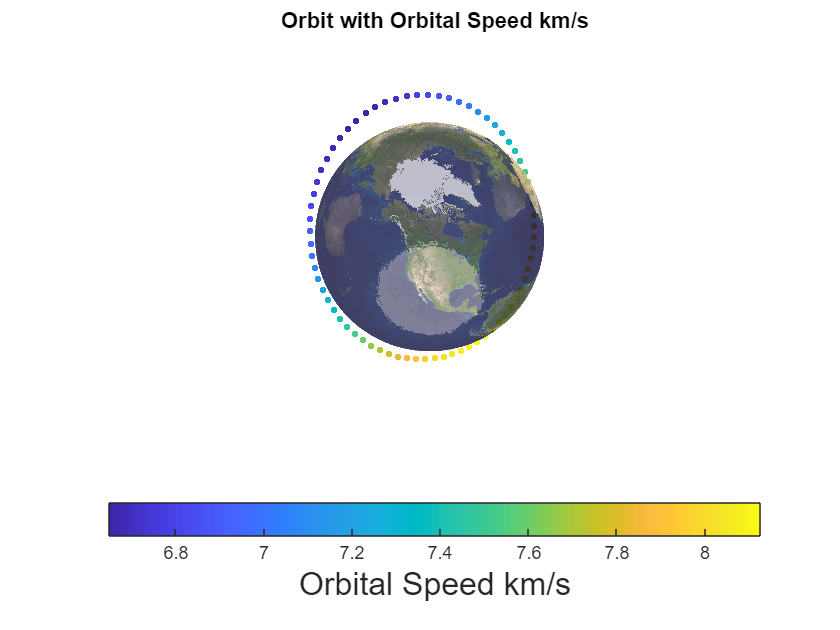

%% calculate magnitude of Rijk using vectorization
mag_Vijk = sum(Vijk.*Vijk,2).^0.5; % uses .* and .^ 

opts_earth.FaceAlpha = 0.2; % makes the earth more transparent

figure
planet3D('Earth',opts_earth);
hold on
scatter3(Rijk(:,1),Rijk(:,2),Rijk(:,3),10,mag_Vijk,'filled')
caxis([min(mag_Vijk) max(mag_Vijk)]); %Note: in Matlab R2022a and later, caxis has been renamed to clim
cb = colorbar("southoutside");
xlabel(cb,'Orbital Speed km/s','FontSize',16,'Rotation',0);
title('Orbit with Orbital Speed km/s')
grid off
axis off
hold off

### **Finding Roots of NonLinear Functions**

Finding roots of functions is a skill that is frequently required when solving engineering problems. For example, one way to solve Kepler's problem is to find the root of a non-linear function of Eccentric anomaly. In Astro 321, you learned the Newton-Rhapson method of finding a root. Matlab has several built-in solvers which can be used to find roots of functions. Frequently, the initial guess is key in successful root finding. One way to determine an appropriate guess is to plot the function. 

#### **Example 8: Finding LaGrange Points (you'll learn a better method in class!)**

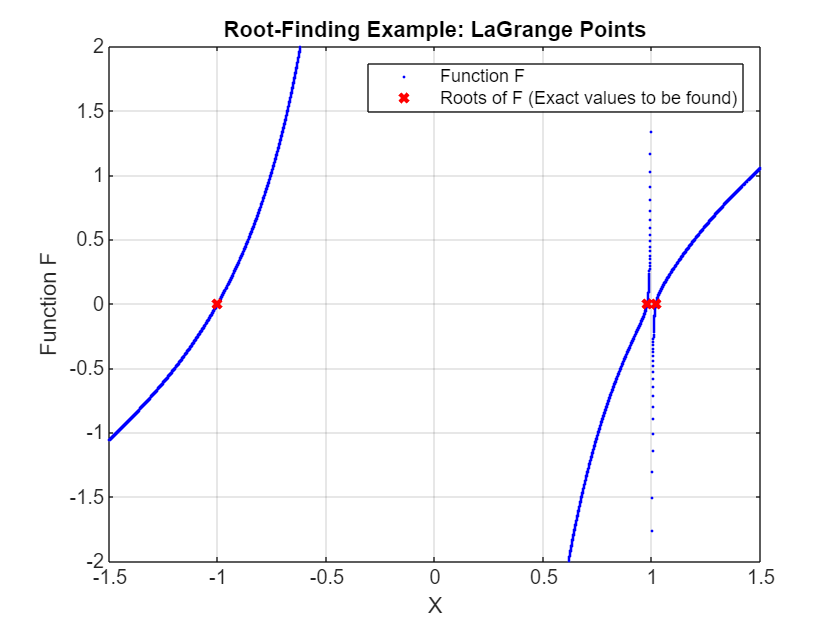

%Define mass parameters for Jupiter and Earth System
muJ=126686531.9;
muE=3202.7121;

mu_star=muE/(muE+muJ); %Calculate mass parameter for the system

X=linspace(-1.5, 1.5, 10000); %set vector of X values over which to plot.

F=X-(1./(((X+mu_star).^2).^0.5).^3).*(1-mu_star).*(X+mu_star)-(1./(((X-1+mu_star).^2).^0.5).^3)*mu_star.*(X-1+mu_star); %Function which we need to find the root of

%Plot the function F to assess possible initial guesses for root finding
figure
plot(X,F,'b.','MarkerSize',4)
hold on
plot(-1.000010531990783,0,'rx','linewidth',2)
plot(0.979764160594868,0,'rx','linewidth',2)
plot(1.020461329101375,0,'rx','linewidth',2)
axis([-1.5 1.5 -2 2])
xlabel('X')
ylabel('Function F')
title('Root-Finding Example: LaGrange Points')
legend('Function F','Roots of F (Exact values to be found)')
grid on

The roots of F correspond to the locations of the colinear Lagrange points. To find the numerical value of these roots, choose a value that is relatively close to the root using the plot.

%Specify initial guesses to find the location of each Lagrange point
L1guess=0.7;
L2guess=1.3;
L3guess=-0.8;

%Solve for actual root using fzero (note: fzero works if the function
%crosses the x-axis. If it does not, e.g., solving for the root of f=x^2,
%fzero will not work. In that case, use a different solver (e.g., fsolve))
fun=@LaGrangeFxn;

%%fzero finds the root of a function if it actually crosses through zero
%% fslove

[L1,FVAL1]= fzero(fun,L1guess) %the output FVAL1 provides the value of the function at the root (won't be exactly zero). You can adjust stopping criteria and options for fzero. See Matlab documentation. 

L1 =    0.979764160361089


FVAL1 =      3.400058012914542e-16


[L2,FVAL2]= fzero(fun,L2guess)

L2 =    1.020461329101569


FVAL2 =     -4.787836793695988e-16


[L3,FVAL3]= fzero(fun,L3guess)

L3 =   -1.000010533318891


FVAL3 =      4.676723011675168e-16


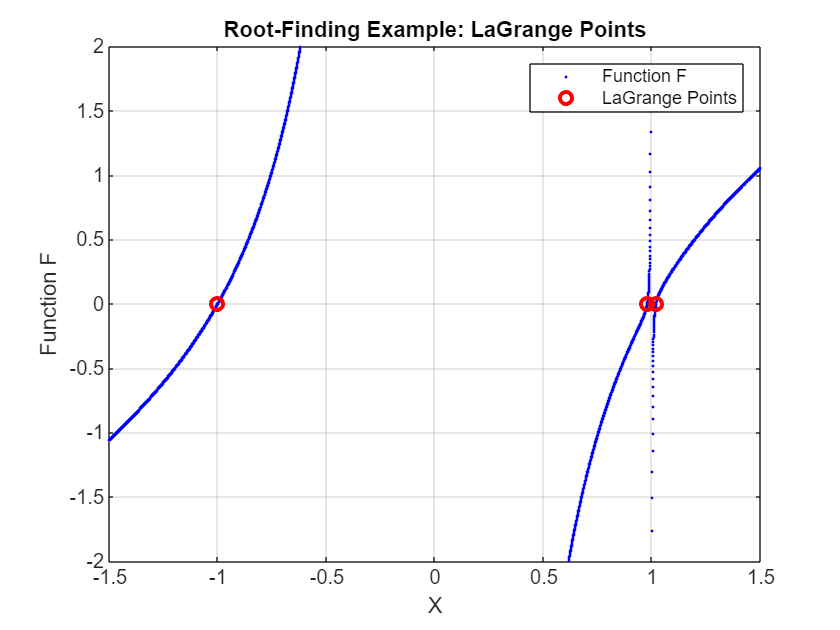

%Plot the LaGrange Points
figure
plot(X,F,'b.','MarkerSize',4)
hold on
plot(L1,0,'ro','linewidth',2)
plot(L2,0,'ro','linewidth',2)
plot(L3,0,'ro','linewidth',2)

axis([-1.5 1.5 -2 2])
xlabel('X')
ylabel('Function F')
title('Root-Finding Example: LaGrange Points')
legend('Function F','LaGrange Points')
grid on

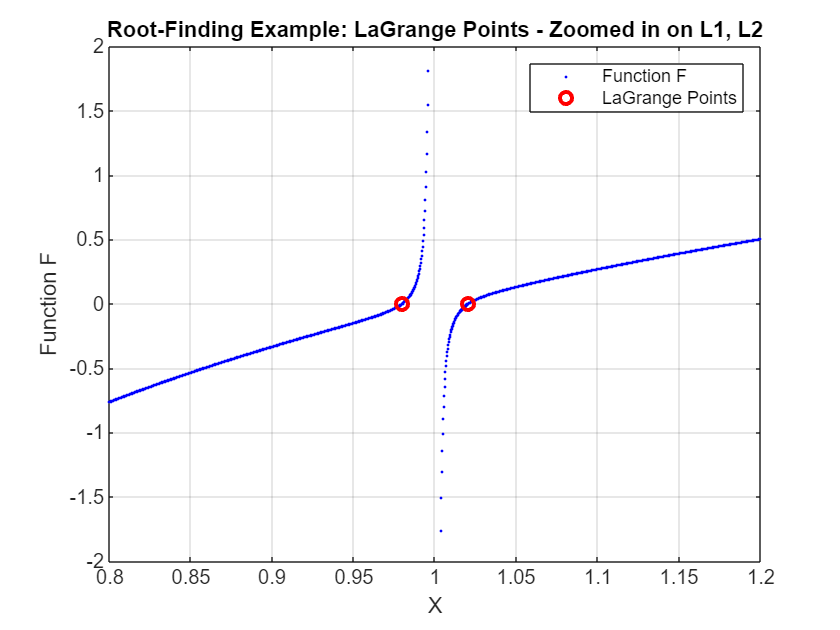


figure
plot(X,F,'b.','MarkerSize',4)
hold on
plot(L1,0,'ro','linewidth',2)
plot(L2,0,'ro','linewidth',2)


axis([0.8 1.2 -2 2])
xlabel('X')
ylabel('Function F')
title('Root-Finding Example: LaGrange Points - Zoomed in on L1, L2')
legend('Function F','LaGrange Points')
grid on

### Numerical Integration and Solving Ordinary Differential Equations

This class focuses on dynamical systems $\frac{\mathrm{d} }{\mathrm{d} t}\textbf{x}(t)=\textbf{f}(\textbf{x}(t),t,\textbf{$\beta$})$ where $\textbf{x}$ is the system state, $\textbf{f}$ is the nonlinear function which depends on the state $\textbf{x}$, time t, and parameters $\textbf{\beta}$.  Specifically, we will be investigating astrodynamical systems which often do not have a closed form solution.  This means one must numerically integrate a set of nonlinear differential equations to solve the problems.  Matlab has built in tools to help solve [Ordinary Differential Equations](https://www.mathworks.com/help/matlab/ordinary-differential-equations.html) (ODEs), several which will be used in this course.

#### Example 8: Modeling the Lorenz equations

This example is from Chapter 7.1 of ["Data-Driven Science and Engineering: Machine Learning, Dynamical Systems, and Control"  by Brunton and Kutz](http://databookuw.com/databook.pdf)

Lorenz equations:


$$\dot{x}=\sigma(y-x)\\
\dot{y}=x(\rho-z)-y\\
\dot{z}=xy-\beta z
$$


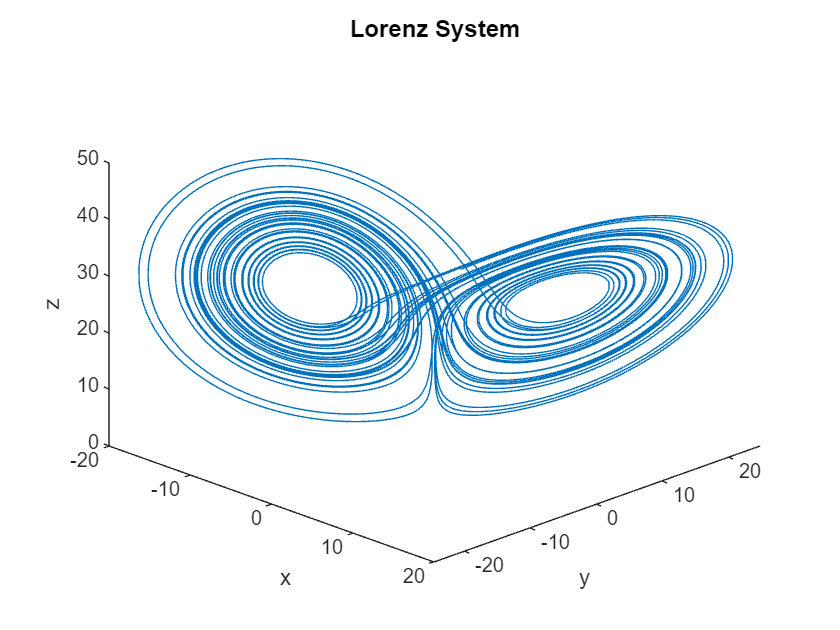

sigma = 10;
rho = 28;
beta = 2.67;

Beta = [sigma;rho;beta]; % Lorenzis parameters (chaotic)
x0=[0; 1; 20]; % Initial condition
dt = 0.001; % define time setp
tspan=dt:dt:50; % define how long to run simulation
options = odeset('RelTol',1e-12,'AbsTol',1e-12*ones(1,3)); 
[t,x]=ode45(@(t,x) lorenz(t,x,Beta),tspan,x0,options);
figure
plot3(x(:,1),x(:,2),x(:,3));
xlabel('x')
ylabel('y')
zlabel('z')
title('Lorenz System','FontSize', 12)
view([45 30])

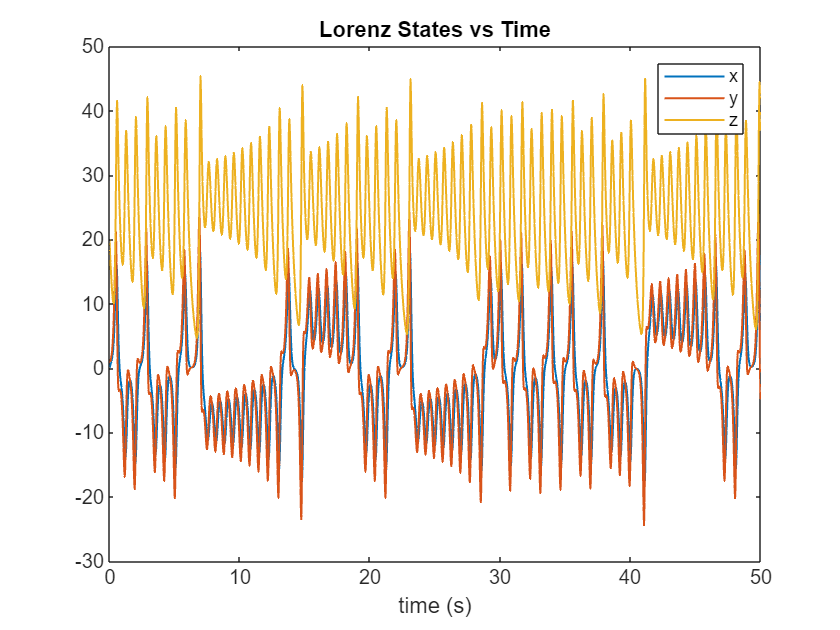

figure
plot(t,x(:,1),t,x(:,2),t,x(:,3),'LineWidth',1)
xlabel('time (s)')
legend('x','y','z')
title('Lorenz States vs Time')

function dx = lorenz(t,x_state,Beta_parameters)
x = x_state(1);
y = x_state(2);
z = x_state(3);
sigma = Beta_parameters(1);
rho = Beta_parameters(2);
beta = Beta_parameters(3);

dx = [
    sigma*(y-x);
    x*(rho-z)-y;
    x*y-beta*z;
    ];
end

function F=LaGrangeFxn(x)
muJ=126686531.9;
muE=3202.7121;
mu_star=muE/(muE+muJ);
F=x-(1./(((x+mu_star).^2).^0.5).^3).*(1-mu_star).*(x+mu_star)-(1./(((x-1+mu_star).^2).^0.5).^3).*mu_star.*(x-1+mu_star);
end
